# Neural and acoustic distance: congruence of networks?

Can we find any correlates between differences of vocal gestures and differences of neural activity?

There are undesirable covariate in the data: systematic other behaviors and corresponding neural response (interaction at the mesh) that correlate only with a certain type of call that by definition have acoustic features themselves really different from other type of call. Because we cannot reliably annotate these other behaviors, we cannot regress them out. So we need to focus on only one call type and see how these are covarying with neural activity.

Linear models of the type Rate ~ Acoustic feature (Gaussian, Gamma, Poisson) have several issues though:

1- We need to find a right time scale to input to the model: small binning increase the noise, but large time scale might crush the information and in particular eliminate any temporal information.

2- to over come the noise we need a large number of repetition, which we currently don't have in our dataset (need to plot here the cumulative time (duration) of vocalizations, which is the true exploitable value as compared to # calls).

Let's do a dimensionality reduction on the neural response and explore neural tuning in that reduced space.

One first idea for exploring neural tuning, to see if there is anything:

The idea here is to represent neural activity of single units into the same basis set of the PCA, then for each unit calculate the distance between pattern of activity around each vocalization and compare that with the distance of vocalizations in the acoustic space

## Representing neural responses in basis set of PCA

% Load the list of cells that show promising vocalizer patterns as
% demonstrated by the PCA/GLMM approach on average KDE over Trill and
% non-Trill calls (see explore_populationSU.mlx)
load('explore_populationSU_data.mat', 'ListCellsVocPCAComponent','MahalDistanceV2','VCells')
% According the above mentioned notebook, 75% of these cells have a time
% resolution obtained with Coherence on Amplitude that is higher than
% 5.5ms. Let's take 5ms as the width of our Gaussian on all cells and all
% spike patterns around vocal production
TR = 5; %in ms
% also according to the above notebook, the smallest Optimal delay between
% neural response and amplitude of the vocaliztaion for optimal values of
% coherence in -74ms, so let's take neural activity only 100ms before
% vocalizations onset
Delay = 100; %in ms
% cells that have enough vocalizer Trills (>8)
ListCells = ListCellsVocPCAComponent(~isnan(MahalDistanceV2(logical(VCells(:,1)),1)));
NC = length(ListCells);

% Obtain a large matrix of all single Trill neural activity from all
% cells NOTE:!!!! Would make sense to sample equally the cells (same number
% of vocalization for each cell, such as not to bias the basis set towards
% some particular cells?
RateTrills = cell(1,NC);
StimDuraMax = nan(NC,1); % gather the maximum duration of vocalization for each cell. The final matrix will be  hard cut at max(StimDuraMin)+100ms
NStims = nan(NC,1);
for cc=1:NC
    % load the cell
    Cell = load(ListCells{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        NStims(cc) = length(IndVoc);
        StimDura = nan(NStims(cc),1);
        for sss=1:NStims(cc)
            StimDura(sss) = round(length(Cell.BioSound{IndVoc(sss),2}.sound) ./(Cell.BioSound{IndVoc(sss),2}.samprate)*10^3);
        end
        if any(abs(StimDura - Cell.Duration(IndVoc))>1)
            fprintf(1,'*** Problem with Cell: duration inconcistency!! ****\n')
            keyboard
            fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
            return
        end
    end
    StimDuraMax(cc) = max(StimDura);

    % calculate the Time varying Gaussian filtered spike rate for each
    % vocalization
    RateTrill_local = nan(NStims(cc),Delay+2000); % Preallocate space for a large matrix of 2000 + Delay ms
    % neural response is a vector that compile all spike counts starting
    % at -100ms (Delay) before stim onset and stop at 2000ms after
    % stim onset
    [YPerStim, YPerStimt] = get_y(Cell.SpikesArrivalTimes_Behav(IndVoc), Cell.Duration(IndVoc),[-Delay 2000],TR);
    RateTrills{cc} = YPerStim';
end

RateTrills_mat = [RateTrills{:}]';
% cut the matrix at mean(Max duration of vocalization) + Delay/2
StimDuraOpt = round(mean(StimDuraMax)/10)*10;
RateTrills_mat = RateTrills_mat(:, 1:StimDuraOpt+1.5*Delay);
% substract the time varying mean
RateTrills_centered = RateTrills_mat - mean(RateTrills_mat)

RateTrills_centered =    -0.0049   -0.0060   -0.0069   -0.0075   -0.0078   -0.0079   -0.0080   -0.0081   -0.0082   -0.0082   -0.0080   -0.0068   -0.0033    0.0054    0.0227    0.0509    0.0879    0.1245    0.1477    0.1478    0.1247    0.0881    0.0511    0.0227    0.0051   -0.0037   -0.0074   -0.0086   -0.0088   -0.0087   -0.0085   -0.0085   -0.0085   -0.0087   -0.0088   -0.0089   -0.0089   -0.0088   -0.0087   -0.0087   -0.0086   -0.0086   -0.0087   -0.0087   -0.0086   -0.0086   -0.0087   -0.0088   -0.0089   -0.0090
   -0.0049   -0.0060   -0.0069   -0.0075   -0.0078   -0.0079   -0.0080   -0.0081   -0.0082   -0.0083   -0.0084   -0.0086   -0.0087   -0.0088   -0.0089   -0.0090   -0.0089   -0.0088   -0.0087   -0.0086   -0.0086   -0.0086   -0.0088   -0.0089   -0.0090   -0.0091   -0.0092   -0.0091   -0.0089   -0.0087   -0.0085   -0.0085   -0.0085   -0.0087   -0.0088   -0.0089   -0.0089   -0.0088   -0.0087   -0.0087   -0.0086   -0.0086   -0.0087   -0.0087   -0.0086   -0.0086   -0.0087   -0.0

[PC,Score,~, ~, VarExpl,~] = pca(RateTrills_mat);

% Plot the variance explained
plot(cumsum(VarExpl), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl)>90,1), '-k',sprintf('90%% at n=%dPC', find(cumsum(VarExpl)>90,1)))
hold off

% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt+Delay/2));title('PCA basis set of spike rate on Trill')
hold off

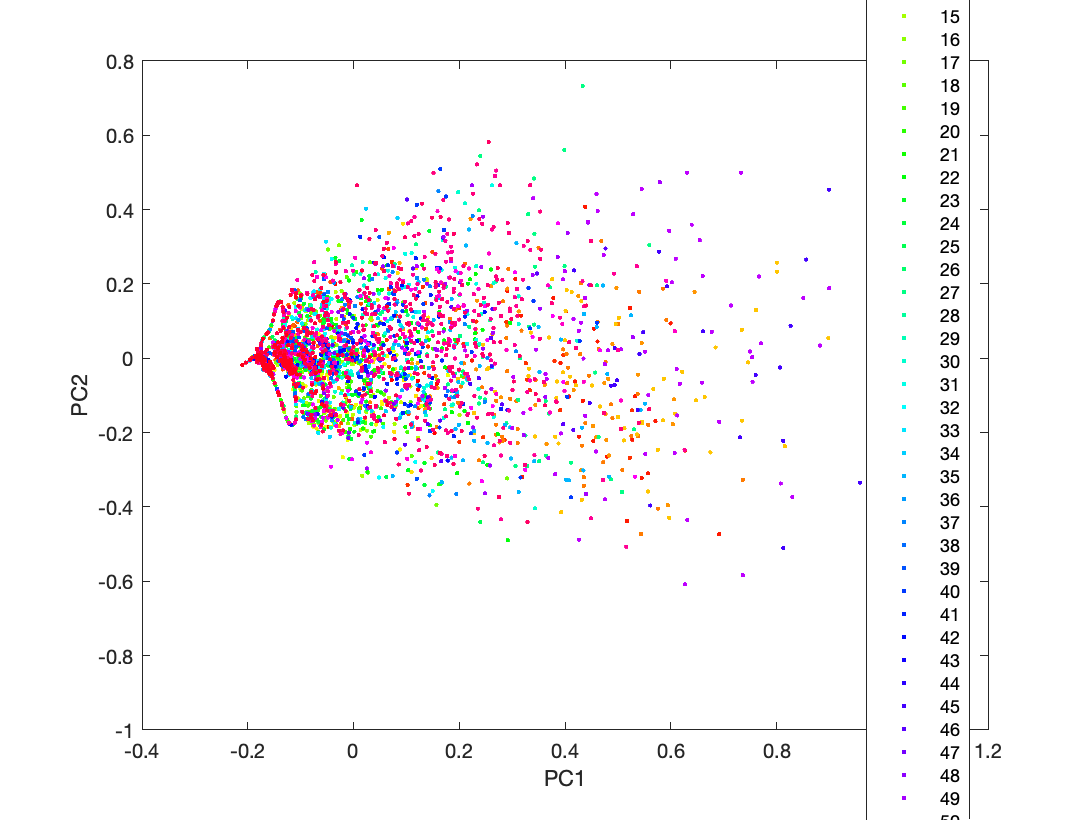

% plot all cells in the PC space
CellID = cell(1,NC);
for cc=1:NC
    CellID{cc} = cc.*ones(1,NStims(cc));
end
CellID = [CellID{:}]';
gscatter(Score(:,1), Score(:,2), CellID)
xlabel('PC1')
ylabel('PC2')

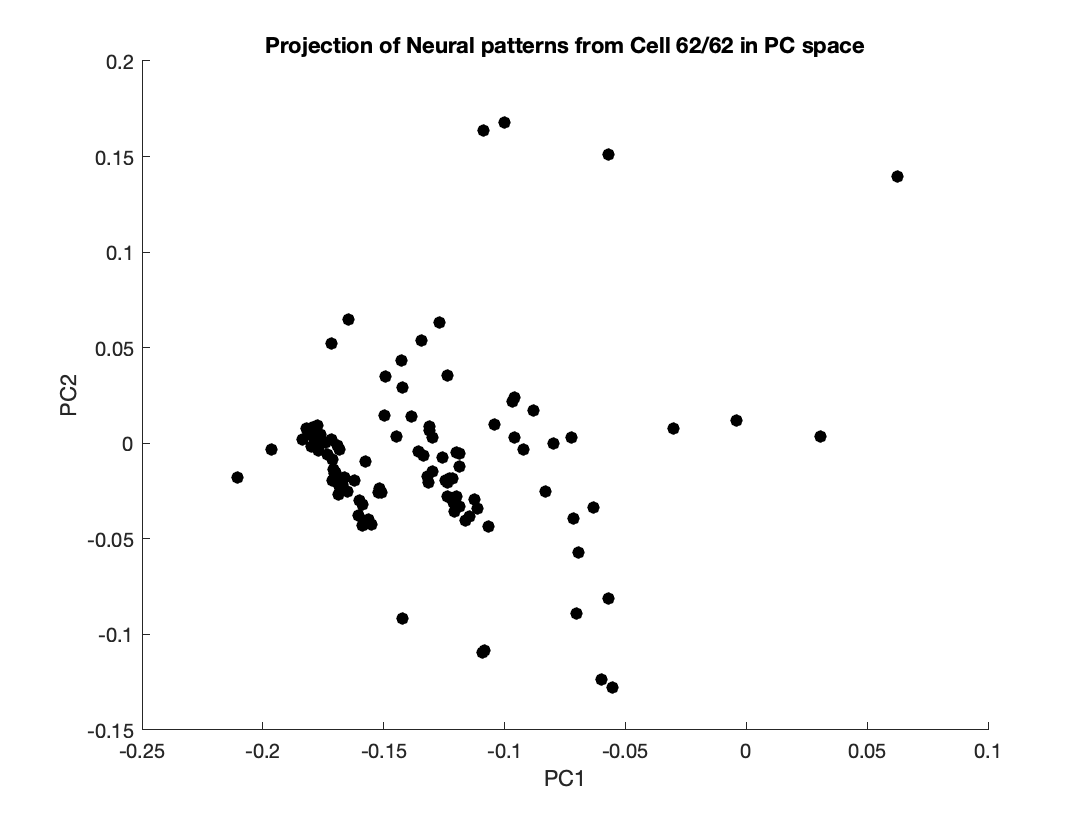

% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% be used as a reference point to calculate distance to other instances
NPC = find(cumsum(VarExpl)>90,1);
NeuralVectorDistance = cell(NC,1);
for cc=1:NC
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(cc)),1:NPC);
    % Calculate the centroid of the cloud of observations
    Centroid = mean(Score_local);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([Score_local; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc} = D(CentralInstance(1), 1:end-1);
%     NeuralVectorDistance{cc} = zeros(length(NStims(cc)),1);
%     Other = setdiff(1:NStims(cc), CentralInstance);
%     NeuralVectorDistance{cc}(Other) = mahal(Score_local(Other,:), Score_local(CentralInstance,:));
Col = zeros(NStims(cc),3);
Col(CentralInstance(1),:) = [1 0 0];
scatter(Score_local(:,1),Score_local(:,2),40,Col, 'filled')
xlabel('PC1')
ylabel('PC2')
title(sprintf('Projection of Neural patterns from Cell %d/%d in PC space', cc, NC))
pause()
end

## Representing Vocalizations in an acoustic basis set

Let's represent Trills iteratively by PCA on a given time varying acoustic feature, substracting the time varying mean acoustic feature

% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
Trills_fund = cell(1,NC);
Trills_sal = cell(1,NC);
StimDuraMax = nan(NC,1); % gather the maximum duration of vocalization for each cell. The final matrix will be  hard cut at max(StimDuraMin)+100ms
NStims = nan(NC,1);
for cc=1:NC
    % load the cell
    Cell = load(ListCells{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        NStims(cc) = length(IndVoc);
        StimDura = nan(NStims(cc),1);
        for sss=1:NStims(cc)
            StimDura(sss) = round(length(Cell.BioSound{IndVoc(sss),2}.sound) ./(Cell.BioSound{IndVoc(sss),2}.samprate)*10^3);
        end
        if any(abs(StimDura - Cell.Duration(IndVoc))>1)
            fprintf(1,'*** Problem with Cell: duration inconcistency!! ****\n')
            keyboard
            fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
            return
        end
    end
    StimDuraMax(cc) = max(StimDura);

    % calculate the Time varying Gaussian filtered spike rate for each
    % vocalization
    RateTrill_local = nan(NStims(cc),Delay+2000); % Preallocate space for a large matrix of 2000 + Delay ms
    % neural response is a vector that compile all spike counts starting
    % at -100ms (Delay) before stim onset and stop at 2000ms after
    % stim onset
    [YPerStim, YPerStimt] = get_y(Cell.SpikesArrivalTimes_Behav(IndVoc), Cell.Duration(IndVoc),[-Delay 2000],TR);
    RateTrills{cc} = YPerStim';
end

function [YPerStim, YPerStimt] = get_y(SAT, Duration,Delay,TR)
        % Calculate the time varying rate applying a gaussian window TR on the
        % spike pattern. The spike pattern considered starts Delay(1) ms
        % before the onset of the vocalization and stops Delay(2) ms after the
        % onset of the vocalization
        % The width of the Gaussian is determined by TR, the Sampling rate
        % is kept as 1kHz
        DebugFig =0;
        % Gaussian window of 2*std equal to TR (68% of Gaussian centered in TR)
        nStd =(max(Duration) - Delay(1) + Delay(2))/10; % before set as 4
        Tau = (TR/2);
        T_pts = (0:2*nStd*Tau) - nStd*Tau; % centered tpoints around the mean = 0 and take data into account up to nstd away on each side
        Expwav = exp(-0.5*(T_pts).^2./Tau^2)/(Tau*(2*pi)^0.5);
        Expwav = Expwav./sum(Expwav);
        
        % Time slots for the neural response
        YPerStimt = Delay(1) : (Delay(2)-1);

        % Preallocate for speed
        YPerStim = nan(length(Duration), length(YPerStimt));
        
        % Loop through the stimuli and fill in the matrix
        for stim=1:length(Duration)
            % Get the spike pattern
            SpikePattern = zeros(1,length(YPerStimt));
            for isp = 1:length(SAT{stim})
                SpikeInd = round(SAT{stim}(isp));
                if (SpikeInd>=Delay(1)) && (SpikeInd<=Delay(2)-1)
                    SpikePattern(SpikeInd - Delay(1) +1) = SpikePattern(SpikeInd - Delay(1) +1) +1;
                end
            end
            
            % Convolve with Gaussian to obtain our smooth time varying spike train
            YPerStim(stim, :) = conv(SpikePattern, Expwav,'same');
            if sum(YPerStim(stim, :))~=sum(SpikePattern)
                YPerStim(stim, :) = YPerStim(stim, :) ./ sum(YPerStim(stim, :)) .* sum(SpikePattern);
            end

            if DebugFig
                figure(200) %#ok<UNRCH>
                clf
                plot(YPerStimt,YPerStim(stim, :), 'LineWidth',2)
                xlabel('Time ms')
                ylabel('Spike Rate mHz (/ms)')
                title(sprintf('Stim %d/%d',stim,length(Duration)));
                %         RemainTime = length(XPerStim_temp) - (length(XPerStim{stim})-1)*(1/Fs*10^3);
                %         XPerStimt{stim} = RemainTime/2+(1/Fs*10^3)*(0:(length(XPerStim{stim})-1));
                hold on
                SpikeTimes = YPerStimt(logical(SpikePattern));
                for ss = 1:length(SpikeTimes)
                    V=vline(SpikeTimes(ss), 'k-');
                    V.LineWidth = 2;
                    hold on
                end
                pause(1)
            end

        end


        
        
    end